% close all;
source = imread('white2.jpg');
texture = imread('weave1.jpg');

[numrows numcols numberOfColorChannelsA] = size(source);

texture = imresize(texture,[numrows numcols]);

depth = 4;

source_ycbcr = Ycbcr(source);
% source_red = source(:,:,1);
% source_green = source(:,:,2);
% source_blue = source(:,:,3);
source_v = source_ycbcr(:,:,3);
% source_red_dwt = wavecdf97(source_red, depth);
% source_green_dwt = wavecdf97(source_green, depth);
% source_blue_dwt = wavecdf97(source_blue, depth);
source_v_dwt = wavecdf97(source_v, depth);

texture_ycbcr = Ycbcr(texture);
% texture_red = texture(:,:,1);
% texture_green = texture(:,:,2);
% texture_blue = texture(:,:,3);
texture_v = texture_ycbcr(:,:,3);
% texture_red_dwt = wavecdf97(texture_red, depth);
% texture_green_dwt = wavecdf97(texture_green, depth);
% texture_blue_dwt = wavecdf97(texture_blue, depth);
texture_v_dwt = wavecdf97(texture_v, depth);

% combined_red_dwt = zeros(size(texture_red_dwt));
% combined_green_dwt = zeros(size(texture_green_dwt));
% combined_blue_dwt = zeros(size(texture_blue_dwt));
combined_v_dwt = zeros(size(texture_v_dwt));

for i=1:size(combined_v_dwt,1)
    for j=1:size(combined_v_dwt,2)
        if (i <= size(combined_v_dwt,1) / (2^depth)) & (j <= size(combined_v_dwt,2) / (2^depth))
%             combined_red_dwt(i,j) = source_red_dwt(i,j);
%             combined_blue_dwt(i,j) = source_blue_dwt(i,j);
%             combined_green_dwt(i,j) = source_green_dwt(i,j);
            combined_v_dwt(i,j) = source_v_dwt(i,j);
        else
%             combined_red_dwt(i,j) = max(source_red_dwt(i,j), texture_red_dwt(i,j));
%             combined_green_dwt(i,j) = max(source_green_dwt(i,j), texture_green_dwt(i,j));
%             combined_blue_dwt(i,j) = max(source_blue_dwt(i,j), texture_blue_dwt(i,j));
            if(abs(source_v_dwt(i,j))>0.2*abs(texture_v_dwt(i,j)))
                combined_v_dwt(i,j) = source_v_dwt(i,j);
            else
                combined_v_dwt(i,j) = texture_v_dwt(i,j);                
            end
        end
    end
end

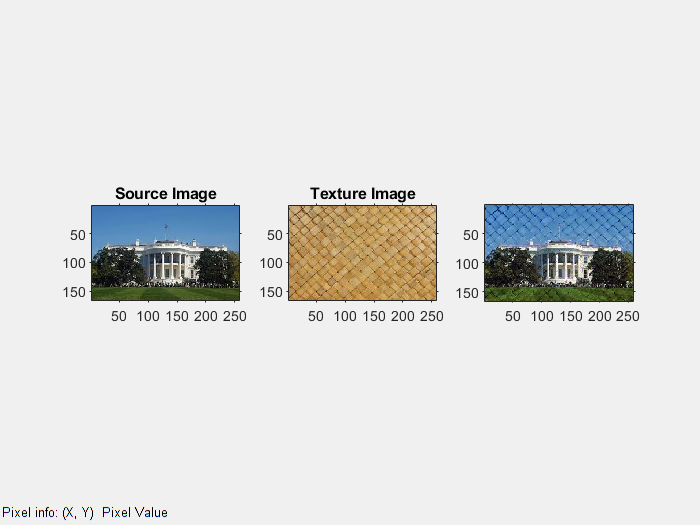

% combined_red = wavecdf97(combined_red_dwt, -1 * depth);
% combined_green = wavecdf97(combined_green_dwt, -1 * depth);
% combined_blue = wavecdf97(combined_blue_dwt, -1 * depth);
combined_v = wavecdf97(combined_v_dwt, -1 * depth);
% combined_img = zeros(size(source));
% combined_img(:,:,1) = combined_red;
% combined_img(:,:,2) = combined_green;
% combined_img(:,:,3) = combined_blue;
combined_ycbcr = zeros(size(source_ycbcr));
combined_ycbcr(:,:,1) = source_ycbcr(:,:,1);
combined_ycbcr(:,:,2) = source_ycbcr(:,:,2);
combined_ycbcr(:,:,3) = combined_v;
combined_img = Ycbcr_invert(combined_ycbcr);
combined_img = uint8(255 * mat2gray(combined_img));
combined_img = myHM(combined_img,source);


figure();
subplot(1,3,1), imshow(source), title('Source Image');
axis on;
axis tight;
daspect([1 1 1]);
subplot(1,3,2), imshow(texture), title('Texture Image');
axis on;
axis tight;
daspect([1 1 1]);
impixelinfo;

subplot(1,3,3),
imshow(mat2gray(combined_img));
axis on;
axis tight;
daspect([1 1 1]);